%%%%%%%%%% 
% Had error in how threshold was being computed and applied to the confusion matrix
% It didnt make sense that reconstruction error was so high for the overall detection of anomalies
% to be so low. These metrics make more sense now--ironically, use of AI for small tasks is not the best.
%%%%%%%%%%
% Compute Reconstruction Errors (MSE)
mseHealthy = mean((testHealthyData - predictedHealthy).^2, 2);mseAnomalous = mean((testAnomalousData - predictedAnomalous).^2, 2);
threshold = min(mseAnomalous);

% Classify anomalies
predictedNormal = mseHealthy < (threshold);
predictedAbnormal = mseAnomalous >= threshold;

% True labels: 0 for normal, 1 for anomaly
trueLabels = [zeros(size(mseHealthy)); ones(size(mseAnomalous))];
trueLabels= logical(trueLabels)

trueLabels = 60×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


% Predicted labels
predictedLabels = [predictedNormal; predictedAbnormal];

% Generate confusion matrix
confMat = confusionmat(trueLabels, predictedLabels);

% Display confusion matrix
disp("Confusion Matrix:");

Confusion Matrix:


disp(confMat);

    28     2
     0    30



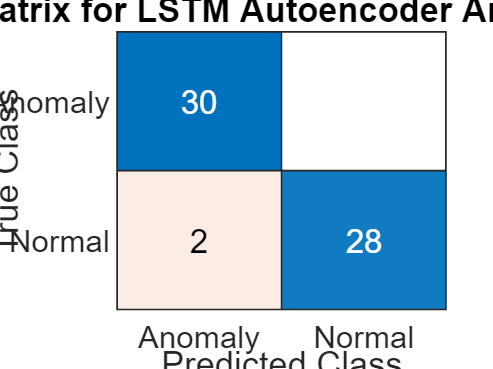


% Plot confusion matrix
figure;
confusionchart(confMat, {'Normal', 'Anomaly'});
title("Confusion Matrix for LSTM Autoencoder Anomaly Detection");